## DKE Introduction to Bioinformatics 2022

# **Assignment 4**

*Elena Perego - i6238107*

## Phylogenetic Trees

Pick a different subset of data from the nextstrain site, download the metadata file and clean it up (see the process I noted I used at the top of this script), so it can be used to build a tree - you may wish to select only a subset of the data, for computational reasons (especially if the sequences are long).  Upload your metadata file with your assignment.  

State a research question you want to explore using your chosen dataset (and that can be answered by building a phylogenetic tree).  Then build a phylogenetic tree to answer your research question and draw some conclusions from your investigation.  

**My research question studies if the higher infection rate of the Omicron variant of COVID-19 is related to higher mutation from the first variant, Alpha, compared to the Delta variant in the United Kingdom.**

## Get the data

I decided to research the United Kingdom because its restriction measures were particularly liberal among Europe which I hypothesize led the virus to spread more. To obtain the dataset to study, all the data for SARS-CoV-2 for all the countries was downloaded from [https://nextstrain.org/ncov/open](https://nextstrain.org/ncov/open) .Then, after importing the data into Excel, it was filtered based on country, the UK, and then all Delta and Omicron variants were kept togther with one sample of the Alpha variant. This lead to 9 genes per variant, Omicron and Delta, and one more for Alpha, in total 19. The data is then imported to MATLAB from Excel.

data = readtable("Bio Informatics\england.csv")

data = 19×23 table
                strain                   date       url         country           recency     genbank_accession      division       emerging_lineage      mutational_fitness    S1_mutations     clade_membership      Nextclade_pango     epiweek        region      current_frequency    pango_lineage          host                           author                     accession           submitting_lab                                                                  originating_lab                                                          rbd_level    logistic_growth
    ____________

Then, all sequences are accessed from the imported table and stored together for further analysis.

sequences = char.empty(0,height(data));
for i = 1:height(data)
    sequences{i} = getgenbank(char(data.genbank_accession(i)),'SequenceOnly',true);
end

## Compute distance matrix

To build the phylogenetic tree, the genetic distances between the different sequences using Jukes-Cantor algorithm, which corrects for possibility of multiple mutations. 

distance_matrix = seqpdist(sequences, squareform=true, UseParallel=true)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


distance_matrix =          0    0.0028    0.0035    0.0039    0.0039    0.0102    0.0106    0.0034    0.0030    0.0053    0.0384    0.0370    0.0173    0.0306    0.0050    0.0050    0.0050    0.0052    0.0052
    0.0028         0    0.0012    0.0017    0.0016    0.0080    0.0086    0.0012    0.0008    0.0031    0.0393    0.0380    0.0176    0.0309    0.0057    0.0057    0.0057    0.0055    0.0059
    0.0035    0.0012         0    0.0016    0.0014    0.0071    0.0076    0.0009    0.0006    0.0029    0.0398    0.0385    0.0182    0.0315    0.0062    0.0062    0.0063    0.0061    0.0064
    0.0039    0.0017    0.0016         0    0.0011    0.0083    0.0089    0.0015    0.0011    0.0035    0.0396    0.0381    0.0175    0.0313    0.0058    0.0058    0.0058    0.0056    0.0060
    0.0039    0.0016    0.0014    0.0011         0    0.0082    0.0088    0.0013    0.0010    0.0033    0.0396    0.0380    0.0177    0.0313    0.0058    0.0058    0.0058    0.0056    0.0060
    0.0102    0.0080    0.0

To better visualize the genetic similiarity of the sequences, the distance matrix is displayed with a color bar showing the closest distances in blue and the furthest ones in yellow.

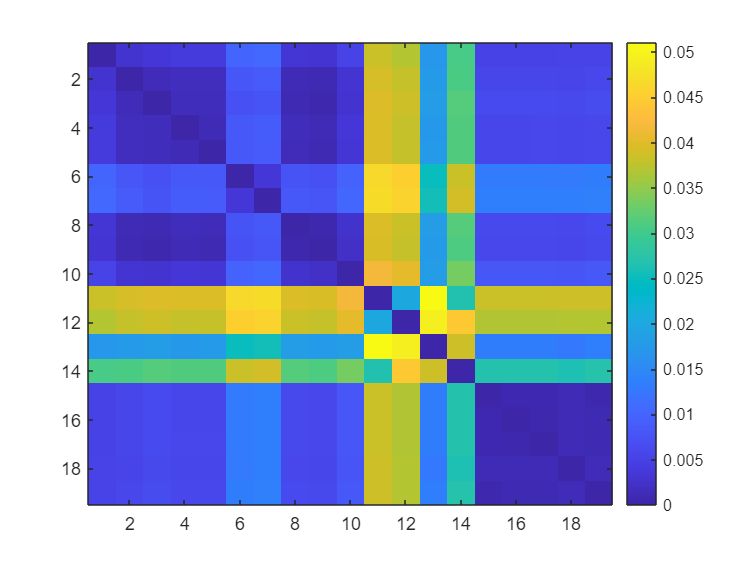

imagesc(distance_matrix);
colorbar

From the result image, the two dark blue squares in the left upper corner and right lower one are visible as they represent the similiarity among variants. Then, it is interesting to notice how the eleventh, twelfth, and fourteenth sequences, which are Omicron, are the genetically furthest, which already gives a first hint regarding the variation within the Omicron variant. Lastly, it is noticeable how the first column, which represents the Alpha sample, becomes gradually lighter as it is compared to Omicron samples, from the eleveth onwards, which is a second intuiton for the research question.

Moreover, once the distance matrix is obtained, to confirm that all Delta samples are genetically closer to the Alpha variant sample. Indeed, the distances of all sequences from this sample are sorted and printed below.

sorted_list = sort(distance_matrix(:,1));
for i = 1:height(data)
    char(data.clade_membership(find(distance_matrix(:,1)==sorted_list(i))))
end

ans = '20I (Alpha, V1)'

ans = '21I (Delta)'

ans = '21J (Delta)'

ans = '21J (Delta)'

ans = '21J (Delta)'

ans = '21J (Delta)'

ans = '21J (Delta)'

ans = 2×13 char array
    '22B (Omicron)'
    '22B (Omicron)'


ans = 2×13 char array
    '22B (Omicron)'
    '22B (Omicron)'


ans = '22B (Omicron)'

ans = '22C (Omicron)'

ans = '22E (Omicron)'

ans = '21J (Delta)'

ans = '21J (Delta)'

ans = '21J (Delta)'

ans = '21L (Omicron)'

ans = '21L (Omicron)'

ans = '21K (Omicron)'

ans = '21K (Omicron)'

Again, as expected, all Delta variants are more similiar to the Alpha than Omicron variant. 

## Build Phylogenetic Tree

Based on the distance matrix, the Phylogenetic Tree can be constructed. However, first, the labels to identify each leaf are formed using the variant and the date to make them all unique from each other.

labels = char.empty(0,height(data));
for i = 1:height(data)
    labels{i} = append(char(data.clade_membership(i)), ' ', datestr(data.date(i)));
end

Then, the Phylogenetic Tree is built using neighbor-joining method and assuming equal variances.

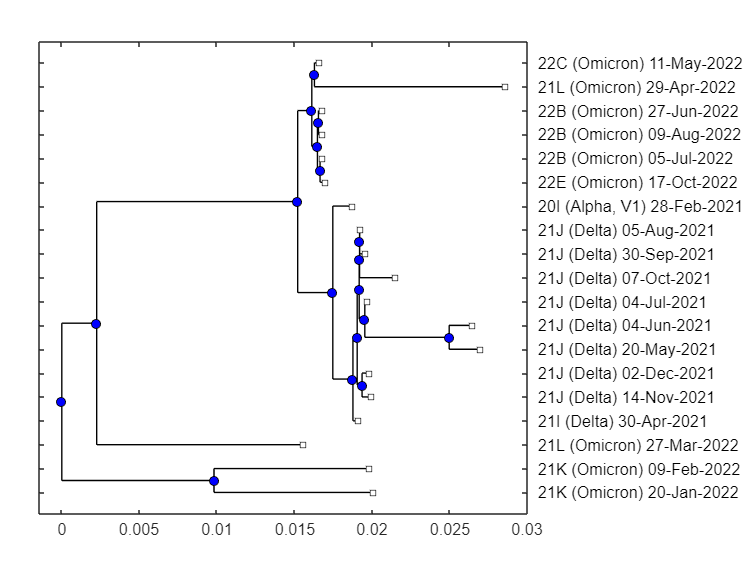

tree = seqneighjoin(distance_matrix, 'equivar', labels);
plot(tree)

From the tree, it can be concluded that the fact that Omicron is more contagious led to more mutations from the original variant for two main reasons. Firstly, three main braches can be identified, two, the upper and lower ones, that contain only Omicron variants and one, the middle one, that contains all Delta sequences and the one Alpha sample. Therefore, since all Delta samples have a closer most recent ancestor to Alpha, these two variants are more related than Alpha with Omicron. This corraborates to the answer to the research question since being further from the original variant means that Omicron mutated most. Secondly, as noticed from the visualization of the distance matrix, the fact that Omicron created two branches shows how this variant is so variagated within itself oppositely to Delta samples that are all grouped together. Indeed, the leafs of the two brances have four most recent common ancestor separeting them. 

For all of these reasons, the shown Phylogenetic Tree shows the higher mutation rate of the variant Omicron of COVID-19 compared to the Delta variant using the first variant Alpha as reference.  